% Clear Workspace
clear all
clc

% Read STL File
% stl1 = stlread("Test Objects\cubeWithHole.STL");
stl1 = stlread("Test Objects\cylinder.STL");

% Create UniformSliceGeneratorObject
sliceHeight = 4;
uSGO1 = FlatUniformSliceGenerator(stl1, sliceHeight)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [236×3 double]
       numOfElements: 236
              points: [120×3 int64]
      sliceThickness: 4
           slicePath: [0×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100



test = uSGO1.slice(0)

test =     50    -5     0
    50    -5     0
    50     0     0
    50     0     0
    50     5     0
    50     5     0
    49    10     0
    49    10     0
    48    15     0
    48    15     0


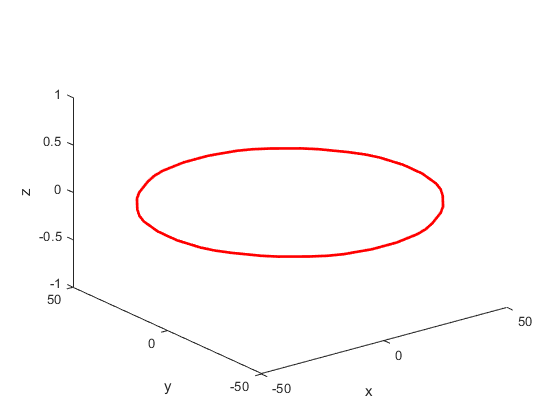

plot3(test(:,1), test(:,2), test(:,3),'-r','LineWidth',2);
xlabel('x')
ylabel('y')
zlabel('z')


% Generate
figure(3)
uSGO1.generateSlices()

ans =     50    -5     0
    50    -5     0
    50     0     0
    50     0     0
    50     5     0
    50     5     0
    49    10     0
    49    10     0
    48    15     0
    48    15     0


ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [236×3 double]
       numOfElements: 236
              points: [120×3 int64]
      sliceThickness: 4
           slicePath: [3146×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100


op = uSGO1.getSlicePath()

op =     50    -5     0
    50    -5     0
    50     0     0
    50     0     0
    50     5     0
    50     5     0
    49    10     0
    49    10     0
    48    15     0
    48    15     0


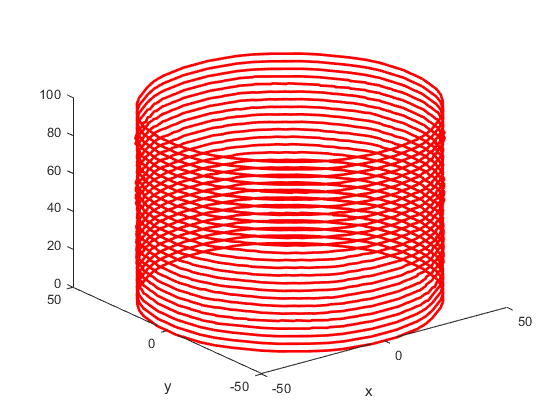


% Show
figure(4)

for i = 0:sliceHeight:max(op(:,3))
    
    plotPoints = op(op(:,3) == i,:);
    plot3(plotPoints(:,1), plotPoints(:,2), plotPoints(:,3),'-r','LineWidth',2);
    hold on

end

xlabel('x')
ylabel('y')
view(3);
hold on